# file main.m

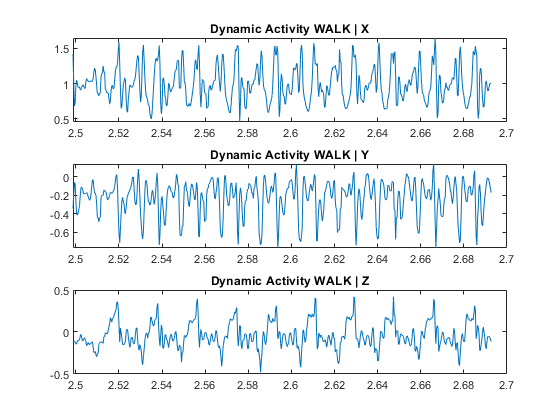

% region constants
DATASETS_DIR = 'datasets';
LABELS_PATH = 'labels.txt';
COLORS = ['-r', '-g', '-b', '-c', '-m', '-y', '-r', '-g', 'b', 'c', 'm'];
ACTIVITIES = ["WALK", "WALK\_UP", "WALK\_DOWN", "SIT", "STAND", "LAY", "STAND\_SIT", "SIT\_STAND", "SIT\_LIE", "LIE\_SIT", "STAND\_LIE", "LIE\_STAND"];
FS = 50;
% end region constants

labels = dlmread(LABELS_PATH, ' ');
datasets = load_datasets(DATASETS_DIR);


plot_activities(datasets, FS, COLORS, labels, ACTIVITIES, 1, 13); % (..., exp, activity)

%plot_datasets(datasets, FS, COLORS, labels, ACTIVITIES);
%plot_dfts(datasets, fs, labels);
[freq, time, num_frames]=calc_stft(datasets(1,:,1) , FS, @hamming, 1, length(datasets(1,:,1)));

t_frame = 0.1280

t_overlap = 0.0640

n_frame = 6

n_overlap = 3

Index exceeds the number of array elements (6).

Error in calc_stft (line 33)
        freq_values = [freq_values, f_frame(index(1))];


plot(1:num_frames, freq, '-b');